# Creating Filters in Swan

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

## Preliminars

In this tutorial we will deal with Filters, which are crucial tools to control the *gray* regions of density fields or avoid checkerboarding problems during simulations. Given any function defined on our domain, Filters basically build a Finite Element Function based in the input function and smoothing it.

Before starting bulding our own filters, let's begin with some preliminars. First, we need a mesh on which the *given* (or input) function will be projected and filtered. Consider the following discretization of a [0,1]x[0,1] domain (Figure 1):

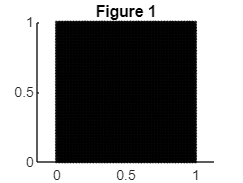

x1 = linspace(0,1,50);
x2 = linspace(0,1,50);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh = Mesh(m);

figure()
mesh.plot()
title('Figure 1')

Moreover, we need a *given *function. As a first example, we are going to create a Characteristic Function, which will be defined on previous [0,1]x[0,1] domain. First as an analytical function:

s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1;
s.mesh    = mesh;
fun       = AnalyticalFunction(s);

Let's also create the same function defined on an unfitted mesh and using a geometrical function:

gPar.type        = 'Circle';
gPar.radius      = 0.3;
gPar.xCoorCenter = 0.5;
gPar.yCoorCenter = 0.5;
g                = GeometricalFunction(gPar);
phiFun           = g.computeLevelSetFunction(mesh);
phi              = phiFun.fValues;

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh              = UnfittedMesh(sUm);
uMesh.compute(phi);

sCF.uMesh = uMesh;
funLS     = CharacteristicFunction.create(sCF);

Previous functions return 0 everywhere except on a disc of height z=1, centered on (0.5,0.5) and radius 0.3. We can see how this characteristic function would look like by projecting it to a P0 FE function (Figure 2):

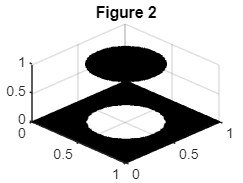

fP0 = fun.project('P0');
fP0.plot()
view(45,45)
title('Figure 2')

## Filters

### P1 Filter

Let's start now creating our first filter: P1. This is formally known as Kernel filter. The operator basically computes an average field, using as reference the patch formed by the degrees of freedom stated in the test function, and expressing the final result in the vectorial base of the trial function. Consider, for instance, a P0 to P1 Kernel filter:

ss.filterType    = 'P1';
ss.mesh          = mesh;
ss.test          = P0Function.create(mesh,1);
ss.trial         = P1Function.create(mesh,1);
filter           = Filter.create(ss);

Now, we can obtain our first P1 function of our characteristic function by means of the following filter public command:

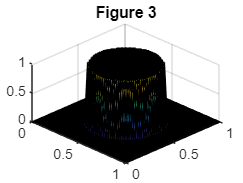

fP1  = filter.compute(fun,'QUADRATICMASS');
fP1.plot()
view(45,45)
title('Figure 3')

The quadrature included as the second input in filter.compute() is the one used to integrate the input function. The idea is to use an enough high order quadrature concerning the linearity of our input function.

Moreover, we can obtain the same result with other configurations of trial and test:





% ClementDiscussion
% funLS

### PDE Filter

Let's create now a PDE filter, which also works for density problems or gradients. This new kind of filter works with additional parameters, being the most important one the LHStype. This parameter can be defined as:

- DiffReactNeumann - just filtering internal boundaries.

- DiffReactRobin - filtering internal and external boundaries.

- AnisotropicDiffReactNeumann - just filtering internal boundaries with a preferential direction.

- AnisotropicDiffReactRobin - filtering internal and external boundaries with a preferential direction.

Let's start by filtering isotropically just the internal boundaries with this filter:

ss.designVarType = 'Continuous';
ss.filterType    = 'PDE';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.scale         = 'MACRO'; % We can use MICRO for microstructural problems
ss.LHStype       = 'DiffReactNeumann'; % if not given, it is DiffReactNeumann by default
filter           = Filter.create(ss);

We can obtain and plot our P1 function (Figure 4) as:

fP1 = filter.compute(fun,'QUADRATICMASS');
fP1.plot()
view(45,45)
title('Figure 4')

Another important parameter that can be controlled is the 'epsilon', standing for the radius of influence. The higher the epsilon, the smoother the obtained solution (Figure 5) and, of course, the higher the amount of numerical information lost. Inherently, epsilon must be at least >=minimum mesh size.

epsilon = 4*mesh.computeMeanCellSize();
filter.updateEpsilon(epsilon);
fP1highEps = filter.getP1Function(fun,'LINEAR');
fP1highEps.plot()
view(45,45)
title('Figure 5')

Let's finish by filtering anisotropically the internal boundaries with this filter:

ss.designVarType = 'Continuous';
ss.filterType    = 'PDE';
ss.quadType      = 'QUADRATIC';
ss.mesh          = mesh;
ss.scale         = 'MACRO';
ss.LHStype       = 'AnisotropicDiffReactNeumann';
ss.CAnisotropic  = [100, 0; 0, 0.01];
ss.aniAlphaDeg   = 0;
filter           = Filter.create(ss);

Here it is necessary to define an expansion matrix CAnisotropic establishing the preferential direction and an aniAlphaDeg angle that rotates this behaviour. In this example, direction X is smoothed with a priority 10000 higher than the corresponding to direction Y. The obtained solution is the following (Figure 6):

fP1 = filter.getP1Function(fun,'LINEAR');
fP1.plot()
view(45,45)
title('Figure 6')

## filer lumpp

## Grid convergence analysis

Error, ClementDiscussion...

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!